# 仿真数据后处理

clear
% 导入仿真结果数据
load("Sim_result.mat")

t=out.Time;
x_g=out.Data(:,1);
y_g=out.Data(:,2);
psi=out.Data(:,3);
beta=out.Data(:,4);
vx=out.Data(:,5);
vy=out.Data(:,6);
phi_r=out.Data(:,7);
delta_f=out.Data(:,8);

% 导入参考数据
load("reference_processed.mat")



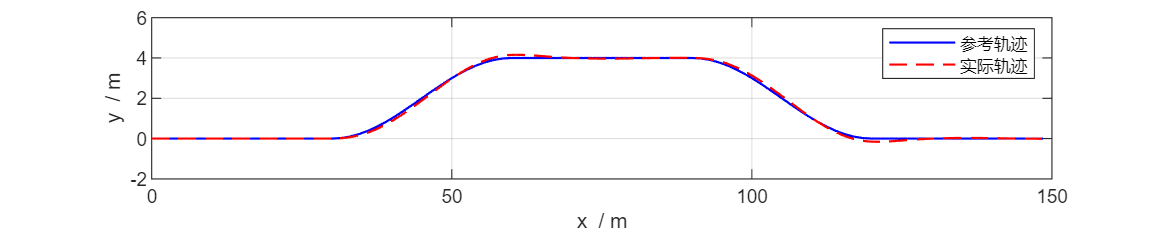


% 轨迹及轨迹误差
figure(Units="centimeters",Position=[5,5,40,8])
hold on
plot(x_ref,y_ref,'-b',LineWidth=1)
plot(x_g,y_g,'--r',LineWidth=1)
hold off
box on
grid on
legend('参考轨迹','实际轨迹')
xlim([0,150])
ylim([-2,6])
xlabel('x  / m')
ylabel('y  / m')

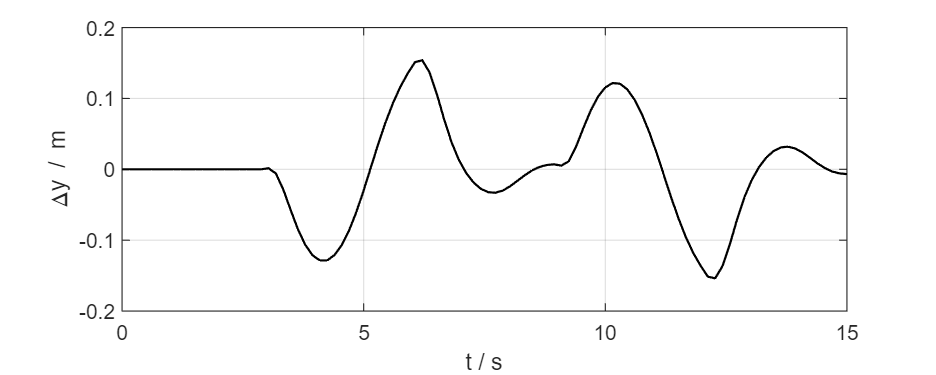


% 轨迹误差

% 重新插值对齐
y_g1=interp1(t,y_g,t_ref);
x_g1=interp1(t,x_g,t_ref);
psi1=interp1(t,psi,t_ref);

figure(Units="centimeters",Position=[5,5,15,6])
plot(t_ref,y_g1-y_ref,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('\Deltay / m')

disp(['轨迹跟踪横向平均误差：',num2str(sum(abs(y_g1-y_ref))/length(y_ref)),' m'])

轨迹跟踪横向平均误差：0.047559 m


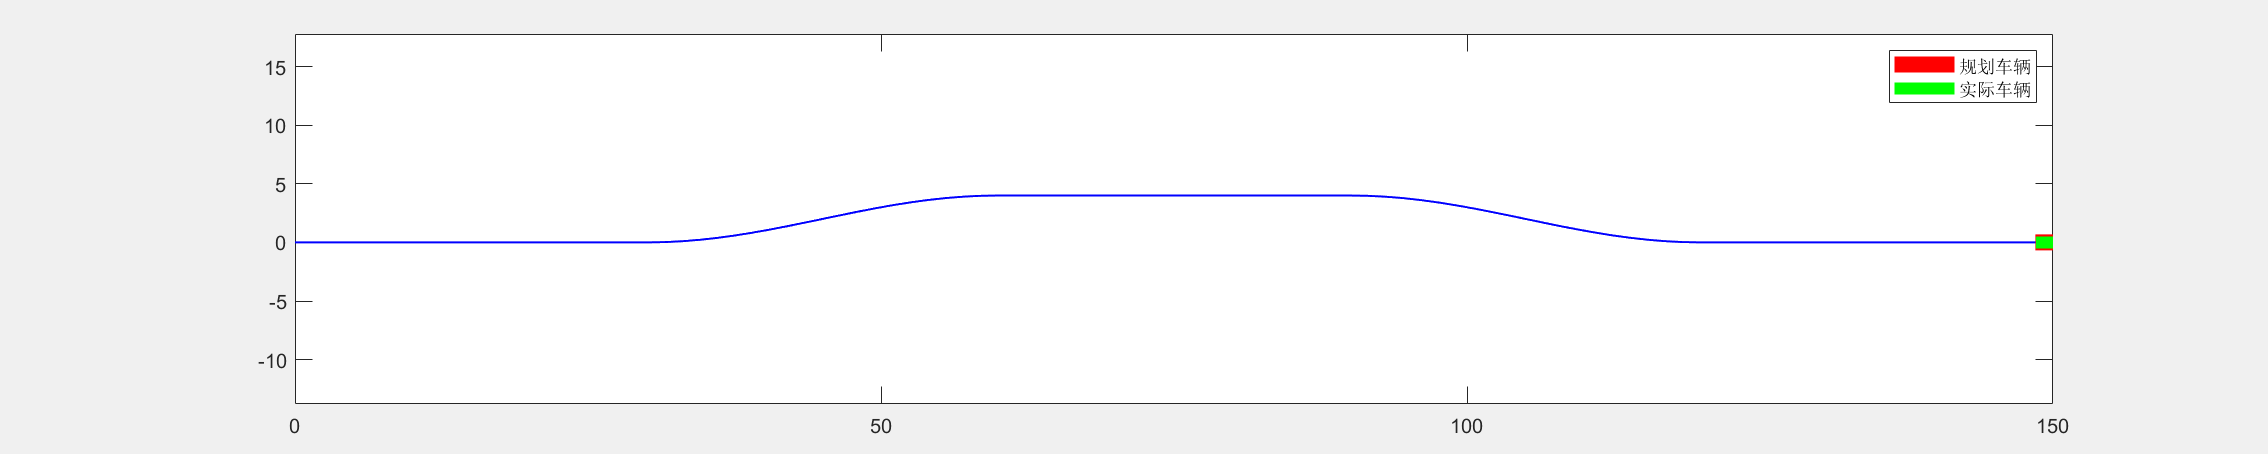

% 动画展示
L=3; % 轴距（近似车长）
v = VideoWriter("result.avi");
open(v)

h=figure(Units="centimeters",Position=[5,5,40,8]);
plot(x_ref,y_ref,'-b',LineWidth=1)
hold on
xlim([0,150])
ylim([-2,6])
axis equal
h.Visible = 'off';
for i=1:length(t_ref)
    if i > 1
        delete(h1); % 清除前一个曲线
        delete(h2); % 清除前一个曲线
    end

    h1=plot([x_ref(i),x_g1(i)+L*cos(Psi_d(i))],[y_ref(i),y_ref(i)+L*sin(Psi_d(i))],'-r',LineWidth=8);
    h2=plot([x_g1(i),x_g1(i)+L*cos(psi1(i))],[y_g1(i),y_g1(i)+L*sin(psi1(i))],'-g',LineWidth=6);
    
    legend([h1,h2],{'规划车辆','实际车辆'})

    drawnow; % 更新图形
    M(i) = getframe;
    writeVideo(v,M(i))

end
hold off
h.Visible = 'on';

close(v)

movie(M,2,5); % (帧结构数组，播放次数，播放帧率）

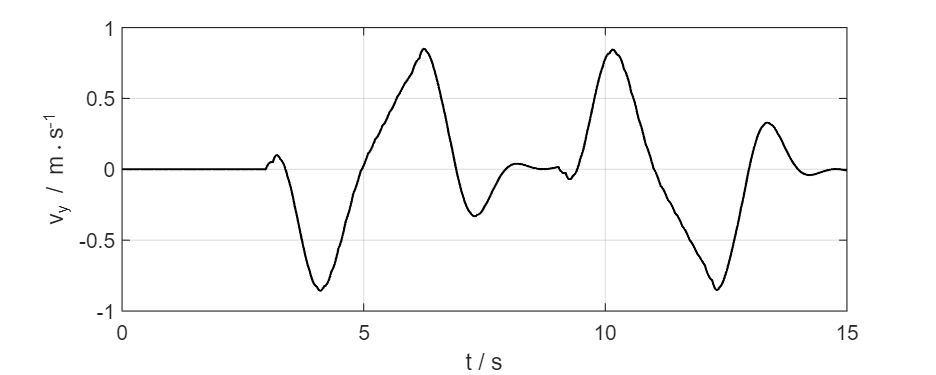

% 车辆状态：横向车速、质心侧偏角、横摆角速度

% 横向车速
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,vy,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('v_y / m\cdots^{-1}')

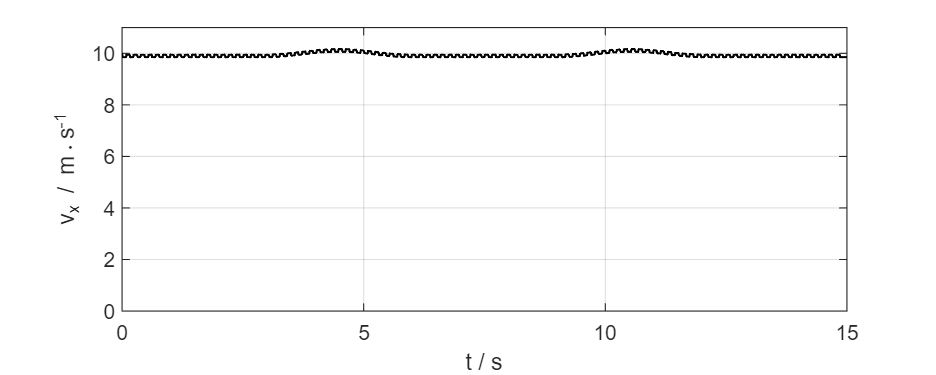

% 纵向车速
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,vx,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('v_x / m\cdots^{-1}')
ylim([0,11])

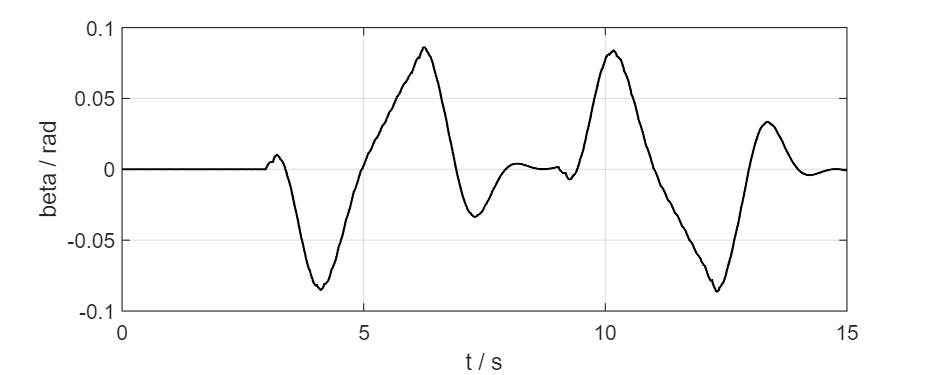



% 质心侧偏角
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,beta,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('beta / rad')

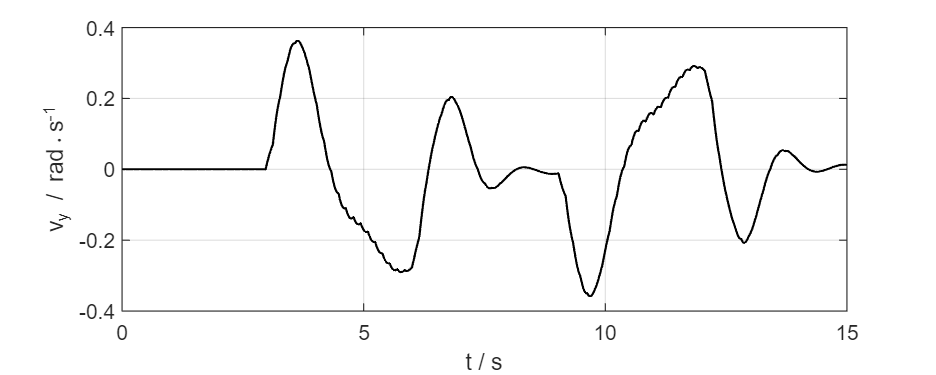


% 横摆角速度
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,phi_r,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('v_y / rad\cdots^{-1}')

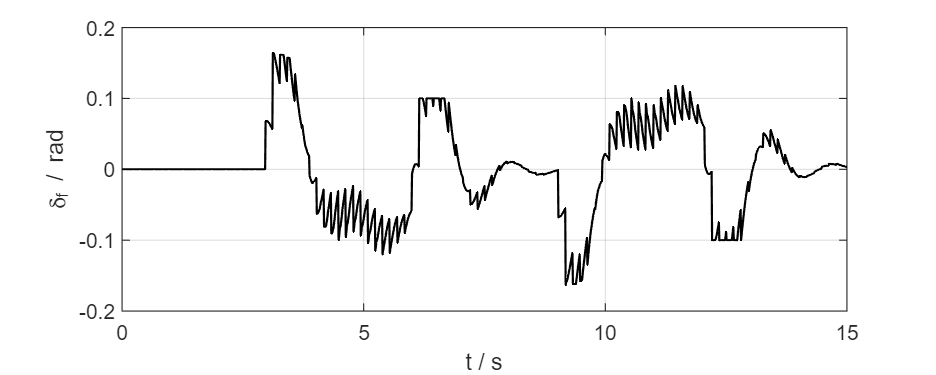

% 前轮转角输入
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,delta_f,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('\delta_f / rad')